
%% P1
% a)
im = [101   244   231   126   249;
      151   249   219     9    64;
      88    93    21   112   155;
      114    55    55   120   205;
      84   154    24   252    63];

F = [-1 0 1 ; -3 0 3; -1 0 1];

outIm = applyFilter(im,F)

outIm =          981         458        -594        -101        -387
        1084         267        -819        -313        -265
         583        -192        -118         397        -465
         412        -304         312         623        -724
         517        -239         359         267        -876




s = sum(abs(outIm(:)))

s = 11657


% b)
im = double(imread('swan.png'));

F = [-1 0 1 ; -3 0 3; -1 0 1];

outIm = applyFilter(im, F);

s = sum(abs(outIm(:)))

s = 2937527

imwrite(uint8(stretch(outIm)), './swanFiltered.png');

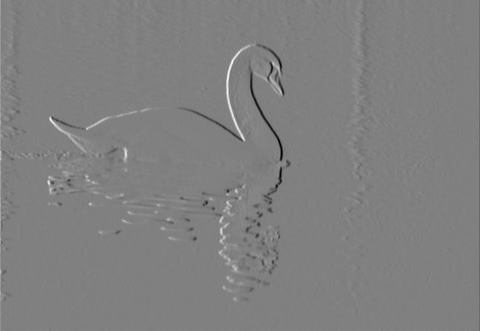

%% P2
% a)
im = zeros(5,5,3);
im(:,:,1) =   [101   244   231   126   249;
                151   249   219     9    64;
                88    93    21   112   155;
                114    55    55   120   205;
                84   154    24   252    63];


im(:,:,2) =   [115   228   195    68   102;
                92    74   216    64   221;
                218   134   123    35   213;
                229    23   192   111   147;
                164   218    78   231   146];


im(:,:,3) =  [  91   201   137    85   182;
                225   102    91   122    60;
                85    46   139   162   241;
                101   252    31   100    69;
                158   198   196    26   239];

F = [ 1 3 0 -3 -1];
eng = computeEngGrad(im,F)

eng =    1.0e+03 *

    1.0482    0.6229    0.6974    0.3918    0.7198
    0.6436    0.3150    0.3294    0.3519    0.4289
    0.3674    0.1294    0.3535    0.3169    0.4061
    0.4456    0.1650    0.1605    0.1390    0.5056
    0.8820    0.4255    0.3753    0.4358    0.8715



s = sum(eng(:))

s = 1.1528e+04



% b)
im = double(imread('face.jpg'));

F = [ 1 3 0 -3 -1];

eng = computeEngGrad(im,F);

s = sum(eng(:))

s = 4.5304e+06

imwrite(uint8(stretch(eng)), './faceEngG.jpg');

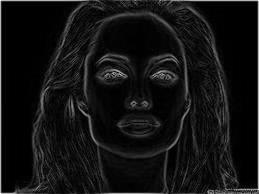

%% P3
% a)
im = [];
im(:,:,1) =   [101   244   231   126   249;
                151   249   219     9    64;
                88    93    21   112   155;
                114    55    55   120   205;
                84   154    24   252    63];


im(:,:,2) =   [115   228   195    68   102;
                92    74   216    64   221;
                218   134   123    35   213;
                229    23   192   111   147;
                164   218    78   231   146];


im(:,:,3) =  [  91   201   137    85   182;
                225   102    91   122    60;
                85    46   139   162   241;
                101   252    31   100    69;
                158   198   196    26   239];


W = [-3 1 -3];
eng = computeEngColor(im,W)

eng =         -461       -1107        -909        -565       -1191
       -1036        -979        -714        -329        -151
        -301        -283        -357        -787        -975
        -416        -898         -66        -549        -675
        -562        -838        -582        -603        -760



s = sum(eng(:))

s = -16094



% b)
im = double(imread('cat.png'));

W = [-3 1 -3];

eng = computeEngColor(im,W);

s = sum(eng(:))

s = -58999407

imwrite(uint8(stretch(eng)), './catEngC.png');

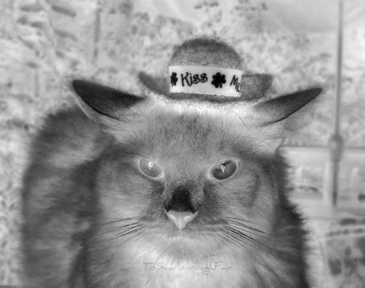

%% P4
% a)
im = [];
im(:,:,1) =   [101   244   231   126   249;
                151   249   219     9    64;
                88    93    21   112   155;
                114    55    55   120   205;
                84   154    24   252    63];


im(:,:,2) =   [115   228   195    68   102;
                92    74   216    64   221;
                218   134   123    35   213;
                229    23   192   111   147;
                164   218    78   231   146];


im(:,:,3) =  [  91   201   137    85   182;
                225   102    91   122    60;
                85    46   139   162   241;
                101   252    31   100    69;
                158   198   196    26   239];


W = [-3 1 -3];
mask = [ -1 1 0 -1 0;...
         1 1 0 -1 1;...
         0 1 0 -1 -1;...
         1 1 0 -1 1;...
         -1 -1 0 1 0];
maskW = 10;

F = [1 3 0 -3 -1];
im4 = cat(3,im,mask);
eng = computeEng(im4,F,W,maskW)


% b)